## Laboratorio 2 - Teoría de Control 2

#### a) Obtenga el modelo en el espacio de estados del sistema

clear
clc
close all

A = [0 1 0; -4 -0.4 0.8; 0 0 -4];
B = [0;0;1.45];
C = [1 0 0];
D = [0];

#### b) Obtenga la respuesta del sistema homogéneo a las condiciones iniciales: [0.24; 0.2; -0.2]

x0 = [0.24; 0.2; -0.2]; % Vector de condiciones iniciales
t = 0:0.01:10; % Vector de tiempo
I = eye(3); % Matriz identidad

Usando la transformada de Laplace:

syms 's';

xt = ilaplace((s*I-A)^-1)*x0;

x1t = subs(xt(1),t);
x2t = subs(xt(2),t);
x3t = subs(xt(3),t);

figure(1)
subplot(4,1,1);
plot(t,x1t,t,x2t,t,x3t);
title("Respuesta a las c.i. (u => 0, c.i. => [0.24 0.2 -0.2]') - Laplace");
legend("x1(t)","x2(t)","x3(t)");

Usando lsim():

u = zeros(size(t));
[T, xt] = lsim(A,B,C,D,u,t,x0);

x1t = xt(:,1);
x2t = xt(:,2);
x3t = xt(:,3);

subplot(4,1,2);
plot(t,x1t,t,x2t,t,x3t);
title("Respuesta a las c.i. (u => 0, c.i. => [0.24 0.2 -0.2]') - lsim()");
legend("x1(t)","x2(t)","x3(t)");

#### c) Obtenga la respuesta completa del sistema considerando las condiciones iniciales anteriores y una entrada escalón de 1.2 KW

Usando la transformada de Laplace:

u = 1.2/s;
xt = ilaplace((s*I-A)^-1*x0 + (s*I-A)^-1*B*u);

t = 0:0.01:10;
x1t = subs(xt(1),t);
x2t = subs(xt(2),t);
x3t = subs(xt(3),t);

subplot(4,1,3);
plot(t,x1t,t,x2t,t,x3t);
title("Respuesta Completa (u => 1.2KW, c.i. => [0.24 0.2 -0.2]') - Laplace");
legend('x1(t)','x2(t)','x3(t)');

Usando lsim():

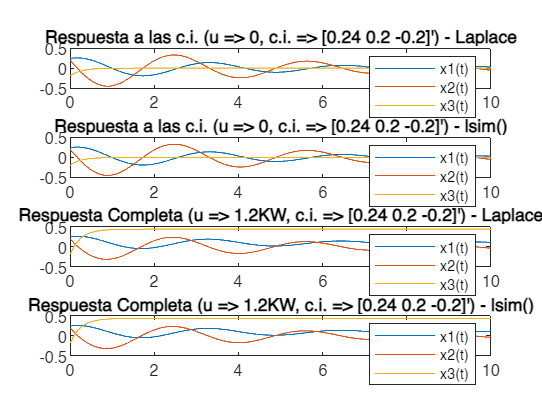

u = 1.2*ones(size(t));
[T, xt] = lsim(A,B,C,D,u,t,x0);

x1t = xt(:,1);
x2t = xt(:,2);
x3t = xt(:,3);

subplot(4,1,4);
plot(t,x1t,t,x2t,t,x3t);
title("Respuesta Completa (u => 1.2KW, c.i. => [0.24 0.2 -0.2]') - lsim()");
legend('x1(t)','x2(t)','x3(t)');